#                        Blind Source Separation

##                                            HW5

                 Mohammadreza Arani         :::::::::::::         810100511

                                                           1402/02/13   

clear ; clc; close all;
load("hw5.mat"); % Load Given Data: D and x 

## Part A: Subset Selection

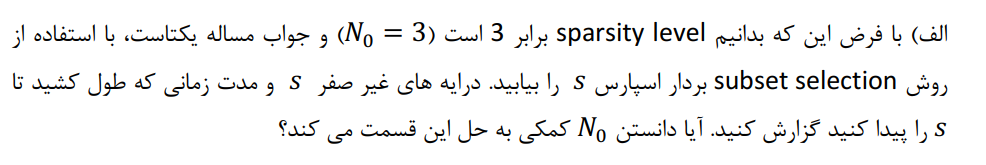

Knowning the Sparsity Level, determines the depth of for loops we need to take to reach the solution! -> O(N0)

% Subset Selection:
N0 =3;

[Row_D,Col_D] = size(D);

S_hat = cell(Col_D,Col_D) ;
Err   = 1e5*ones(Col_D,Col_D,Col_D)  ;
minErr = Err(1,1,1);
tic;
% Sapesity Level Determines the depth of for loops! --> in this 
for i=1:Col_D-N0+1
    for j=i+1:Col_D-N0+2
        for k = j+1:Col_D-N0+3

        s_hat = pinv([D(:,i),D(:,j),D(:,k)])*x  ;
        S_hat{i,j} = s_hat;
        Err(i,j,k) = norm(x-[D(:,i),D(:,j),D(:,k)]*s_hat,2) ; % Calculate the error using norm2

        if(Err(i,j,k)<minErr)% Choose Best Columns:
            best_i = i;
            best_j = j;
            best_k = k;
            best_s_hat = s_hat;
            best_D_sub = [D(:,i),D(:,j),D(:,k)];
            minErr = Err(i,j,k);
        end

        end
    end
end
% Choose Best Columns:

delta_t_subset = toc;

disp("Consumed Time: "+ delta_t_subset+"(s)")

Consumed Time: 0.78692(s)


disp("Min Err: "+minErr)

Min Err: 6.7056e-15


disp("s_hat equals to: ")

s_hat equals to: 


disp(best_s_hat)

    5.0000
    7.0000
   -3.0000



disp("D_sub equals to: ")

D_sub equals to: 


disp(best_D_sub)

   -0.0978    0.4338   -0.7468
   -0.3758   -0.3259   -0.1739
    0.4854    0.2182   -0.1654
    0.4276    0.1064   -0.3020
    0.2960   -0.0258   -0.2809
    0.2291   -0.2758    0.2044
    0.3132    0.1605   -0.3697
    0.2993    0.4324    0.0291
    0.1699    0.2625   -0.1799
    0.2723    0.5369   -0.0543



disp(" Best Indices Are ")

 Best Indices Are 


disp([best_i , best_j , best_k]')

     3
     6
    54



## Part B: Subset Selection using Norm2 Minimization

This Method works fine when s is saprse itself! -->> Checking s- satus:

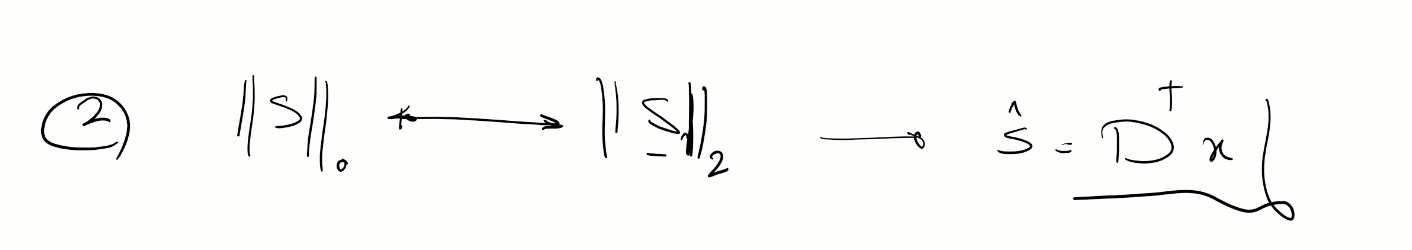

s = pinv(D)*x;
disp(s')

  Columns 1 through 11

   -0.8779   -0.2642    1.5206    0.5541   -0.0881    1.7056   -0.4224   -0.6219   -0.1926   -0.5498   -0.9494

  Columns 12 through 22

    0.2295    0.7217   -0.5231    0.8819    1.0944   -0.1561   -0.2717    0.7519    0.1938    0.0893    0.6346

  Columns 23 through 33

   -1.1332    0.2557   -0.1637    0.8393   -0.1203   -0.4728    0.3206    0.1317    0.3394   -0.8016   -0.4127

  Columns 34 through 44

    0.3028    1.0453   -0.7418   -0.4494    0.5399    0.2173    0.2408   -0.2003    0.6208    0.1933    0.0180

  Columns 45 through 55

   -0.0023   -0.5883   -0.0615    0.6042   -1.0018   -0.3153   -0.3747    0.1485    0.1670   -1.0062    0.7273

  Columns 56 through 60

   -0.1761   -0.4949    0.1770    0.4521   -0.4678



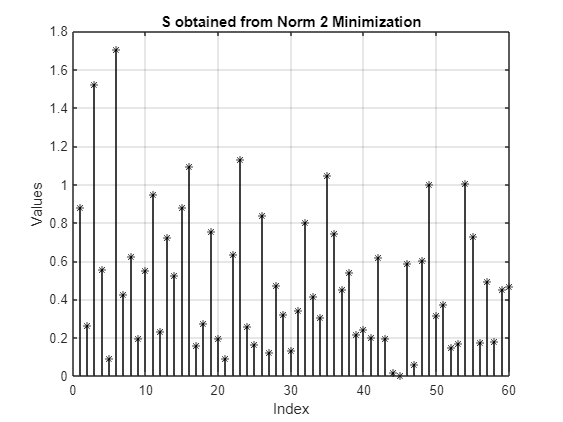

% s does not sound like a sparse matrix -->>> This method is not fine!
% --->>> N0 prior knowledge is not useful in this Method!
stem(abs(s),'black*');
title("S obtained from Norm 2 Minimization")
ylabel("Values")
xlabel("Index")
grid on

 [ sorted_Norm2_S , sorted_indices ] = sort(abs(s),'descend');




## Part C: Matching Pursuit

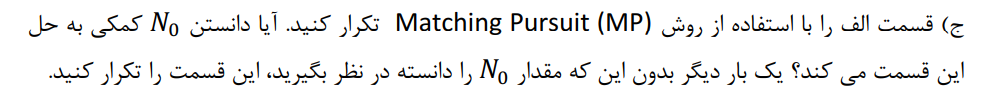

xr = x;
Chosen_IDX = 100+zeros(1,N0);

tic;
B = D;
for  i=1:N0
    
    
    if(i>1)
    B(:,Chosen_IDX(i-1)) = [];
    end
    Corr_matrix = repmat(xr,1,Col_D-i+1).*B;
    Corr_sum = sum(Corr_matrix,1); % Summation for each Column -->> a Row Vector
    [Value,Idx] = max(Corr_sum); % Choosing Best Fitted
    if(sum(Idx>Chosen_IDX)>0)
        Idx  = Idx + sum(Idx>Chosen_IDX) ;
    end
    Chosen_IDX(i) =  Idx;
    xr = x - Value*D(:,Idx); % xr = x  - <x,di>di

end
delta_t_MP = toc;

disp("Elapsed Time (MP): "+ delta_t_MP+"(s)");

Elapsed Time (MP): 0.0037923(s)


disp(" Best Indices Are ")

 Best Indices Are 


disp(Chosen_IDX)

     6     3    55



## MP Not Knowing N0:

Knowing N0 Helps alot in finding the best columns rapidly due to the fact that the MP algo is O(N0) when known and O(Col_D) when N0 is not known!

We then put an stopping Criteria -- >> This Compensates the number of iterations we have to cover until convergence!

xr = x;
Chosen_IDX_2 = inf+zeros(1,Col_D);
thresh = 1e-1;
tic;
B = D;
for  i=1:Col_D
    
    B = D;
    if(i>1)
    B(:,Chosen_IDX_2(1:i-1)) = [];
    end
    Corr_matrix = repmat(xr,1,Col_D-i+1).*B;
    Corr_sum = sum(Corr_matrix,1); % Summation for each Column -->> a Row Vector
    [Value,Idx] = max(Corr_sum); % Choosing Best Fitted
    if(sum(Idx>Chosen_IDX_2)>0)
        Idx  = Idx + sum(Idx>Chosen_IDX_2) ;
    end
    Chosen_IDX_2(i) =  Idx;
    xr = x - Value*D(:,Idx); % xr = x  - <x,di>di
    % Stop Criteria:
    s_hat = pinv(D(:,Chosen_IDX_2(1:i)))*x ;
    if(norm(x - D(:,Chosen_IDX_2(1:i))*s_hat ,2)<thresh )
        break;
    end

end
delta_t_MP_2 = toc;

disp("Elapsed Time (MP): "+ delta_t_MP_2+"(s)");

Elapsed Time (MP): 0.015384(s)


disp(" Best Indices Are ")

 Best Indices Are 


disp(Chosen_IDX_2(Chosen_IDX_2<Col_D+5))

     6     3    55    16    38    41    40    39    21    26



## Part D: Orthogonal MP (OMP)

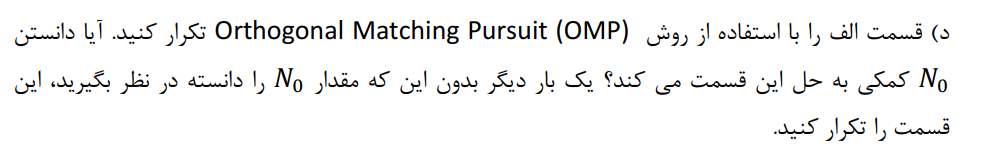

xr = x;
Chosen_IDX_3 = inf+zeros(1,Col_D);
thresh = 1e-6;
tic;
B = D;
for  i=1:N0
    
    B = D;
    if(i>1)
    B(:,Chosen_IDX_3(1:i-1)) = [];
    end
    Corr_matrix = repmat(xr,1,Col_D-i+1).*B;
    Corr_sum = sum(Corr_matrix,1); % Summation for each Column -->> a Row Vector
    [Value,Idx] = max(Corr_sum); % Choosing Best Fitted
    if(sum(Idx>Chosen_IDX_3)>0)
        Idx  = Idx + sum(Idx>Chosen_IDX_3) ;
    end
    Chosen_IDX_3(i) =  Idx;
    
    % Update Coefficients:
    if(i>1)
        D_sub_omp = D(:,Chosen_IDX_3(1:i)) ;
        xr = xr - D(:,Chosen_IDX_3(1:i))*(pinv(D_sub_omp)*xr);

    else 
        xr = x - Value*D(:,Idx); % xr = x  - <x,di>di
    end
    % Stop Criteria:
%     if(norm(x - D(:,Chosen_IDX_3(1:i)) ,2)<thresh )
%         break;
%     end

end
delta_t_OMP = toc;

disp("Elapsed Time (OMP): "+ delta_t_OMP+"(s)");

Elapsed Time (OMP): 0.0056359(s)


disp(" Best Indices Are ")

 Best Indices Are 


disp(Chosen_IDX_3(Chosen_IDX_3<Col_D+5))

     6     3    22



## OMP --- Not Knowing N0

xr = x;
Chosen_IDX_4 = inf+zeros(1,Col_D);
thresh = 1e-1;
tic;
B = D;
for  i=1:Col_D
    
    B = D;
    if(i>1)
    B(:,Chosen_IDX_4(1:i-1)) = [];
    end
    Corr_matrix = repmat(xr,1,Col_D-i+1).*B;
    Corr_sum = sum(Corr_matrix,1); % Summation for each Column -->> a Row Vector
    [Value,Idx] = max(Corr_sum); % Choosing Best Fitted
    if(sum(Idx>Chosen_IDX_4)>0)
        Idx  = Idx + sum(Idx>Chosen_IDX_4) ;
    end
    Chosen_IDX_4(i) =  Idx;
    xr = x - Value*D(:,Idx); % xr = x  - <x,di>di
        % Update Coefficients:
    if(i>1)
        D_sub_omp = D(:,Chosen_IDX_4(1:i)) ;
        xr = xr - D(:,Chosen_IDX_4(1:i))*(pinv(D_sub_omp)*xr);
    end

    % Stop Criteria:
    s_hat = pinv(D(:,Chosen_IDX_4(1:i)))*x ;
    if(norm(x - D(:,Chosen_IDX_4(1:i))*s_hat ,2)<thresh )
        break;
    end

end
delta_t_OMP_2 = toc;

disp("Elapsed Time (OMP): "+ delta_t_OMP_2+"(s)");

Elapsed Time (OMP): 0.0099377(s)


disp(" Best Indices Are ")

 Best Indices Are 


disp(Chosen_IDX_4(Chosen_IDX_4<Col_D+5))

     6     3    22    37     5    21    33    42    41    40



## Part E:   BP (Basis Pursuit)

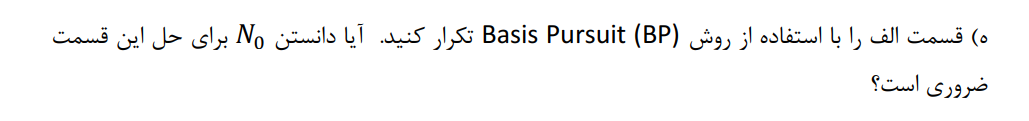

% - Solution of Hw5- part e
load('hw5.mat')
[M,N]=size(D);
N0=3;
% Linear Programming
f=ones(2*N,1);
Aeq=[D -D];
beq=x;
lb=zeros(2*N,1);
tic;
yhat = linprog(f,[],[],Aeq,beq,lb,[]); % Linear-Programming: given Cost function: (f) + Equality Constraints with respect to Variables

Optimal solution found.



% in Matrix Form

splus=   yhat(1:N);
sminus=  yhat(N+1:end);
sBP=     splus-sminus;


posBP=find(abs(sBP)>0.01)'; % Choose Nonzero Elements
delta_t_LinP = toc;
disp("Elapsed Time (LP): "+ delta_t_LinP+"(s)");

Elapsed Time (LP): 0.074427(s)


disp('BP:')

BP:


[posBP;sBP(posBP)'] 

ans =     3.0000    6.0000   54.0000
    5.0000    7.0000   -3.0000


## Part F: IRLS (Iteratively Rewighted Least Square):

load("hw5.mat");
w=ones(N,1);
MAXITER=100;
threshold_IRLS = 1e-3;
tic;
for i = 1:MAXITER

    W=diag(w);
    y=pinv(D*(W^-1))*x;
    S_irls=y./sqrt(w);


    High_Val = 1e+10;
    Low_Val  = 1e-10;
    for n=1:N


        if abs(S_irls(n))<threshold_IRLS
            w(n)=High_Val;   % In case of Low Value of s
        elseif abs(S_irls(n))>1e6
            w(n)=Low_Val;   % In case of High Vlaue of s
        else
            w(n)=1./abs(S_irls(n));  % Regularly
        end

    end




end
delta_t_IRLS = toc;

disp("Elapsed Time (IRLS): "+ delta_t_IRLS+"(s)");

Elapsed Time (IRLS): 0.092848(s)



IRLS_Index=find(abs(S_irls)>0.1)';
disp('IRLS Solution:')

IRLS Solution:


disp(IRLS_Index) 

     3     6    54



% The results are the same as the BP and the MP!
disp("S value according to chosen Indexes: "  + S_irls(IRLS_Index) )

    "S value according to chosen Indexes: 2.924"
    "S value according to chosen Indexes: 3.6593"
    "S value according to chosen Indexes: -2.0801"

